# TP 1 : Identification de systèmes

ASTIC Hugo & BARCELLA Léo

18/10/2024

### Introduction

Le but de ce TP est de mettre en pratique les méthodes d'identifications vues en cours d'AC441 : ARX et ARMAX. Et aussi de voir l'effet de leurs différents paramètres.

% Définition des constantes
Ts = 1; % [s]
N = 50;
varBruit = 0;

#### Définition du système

Nous allons utiliser la fonction `idpoly`. Cette fonction calcule la fonction de transfert du système à temps discret dépendant des polynomes A, B, C, D, F.


$$A\left(s\right)Y\left(s\right)=\frac{B\left(s\right)}{F\left(s\right)}U\left(s\right)+\frac{C\left(s\right)}{D\left(s\right)}E\left(s\right)$$


## 1. Méthodes d’estimation non paramétriques

### 1.1 Etude de l’influence du nombre d’échantillons de mesure

% Définition des polynomes de notre système
A  = [1, -1.5, 0.7];
B = [0, 1, 0.5];
C = 1;
D = 1; F = 1;

sys = idpoly(A,B,C,D,F, varBruit, Ts);
href = impulse(sys, N);

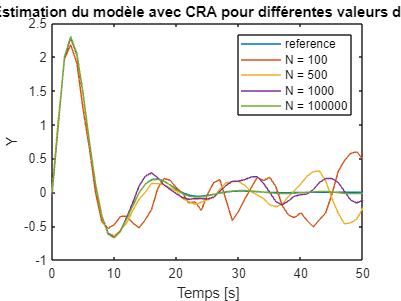

% Définition de nos inputs

N_vector = [100, 500, 1000, 100000];
x = [0:1:50];

% Figure
figure;
plot(x, href, 'DisplayName', 'reference')
hold on;
error = zeros(length(N_vector),1);
for i=1:length(N_vector)
    htest = estimateImpulse(N_vector(i), sys, Ts);
    plot(x,htest, 'DisplayName', ['N = ' num2str(N_vector(i))]);
    error(i) = mean(abs(href - htest));
end
title('Estimation du modèle avec CRA pour différentes valeurs de N');
xlabel("Temps [s]"); ylabel("Y");
legend show; % Afficher la légende
hold off; % Désactiver hold on si nécessaire

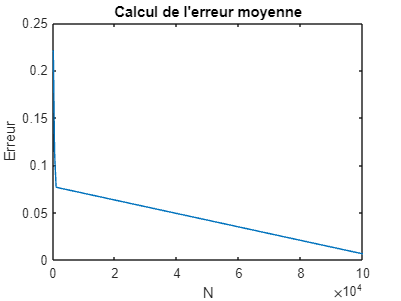


figure;
plot(N_vector, error);
title("Calcul de l'erreur moyenne");
xlabel("N"); ylabel("Erreur");



%plot(x, href, x, htest100, x, htest500, x, htest1000);
%legend("Reference", "N=100 points", "N=500 points", "N=1000 points")


*Question 1 :** Conclure quant à l’influence du paramètre N sur la précision du modèle obtenu.*

 On peut voir sur le graphique précédente que lorsque N augmente, la précision de notre estimation se rapproche de notre système.

*Question 2 :** Pourquoi un N grand permet-il d’avoir une meilleure modélisation ?*

Prendre un N plus grand permet d'avoir plus de précision sur la sortie et d'avoir un signal riche en différentes informations (fréquences, pentes, allure des courbes...).

*Question 3 :** En pratique quel est l’inconvénient de prendre N très grand ?*

Lorsque l'on prend un N très grand, le temps de l'étude du système devient aussi grand que N. Entrainant ainsi l'arrêt du système de production pendant toute la période de test. Il sera donc nécessaire de faire un compromis entre la durée du test et la précision du modèle.

### 1.2 Etude de l’influence de la variance du bruit

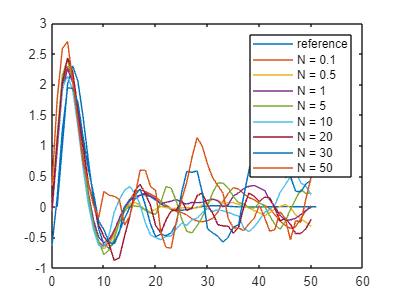

% Définition des polynomes de notre système
sigmaBruit = [0.1, 0.5, 1, 5, 10, 20, 30, 50];
N = 1000;
sys = idpoly(A,B,C,D,F, 0, Ts); % Sans bruit
href = impulse(sys, 50); % Réponse idéale
x = 0:1:50;
error = zeros(length(N_vector),1);

figure;
plot(href, 'DisplayName', 'reference');
hold on;
for i=1:length(sigmaBruit)
    sys = idpoly(A,B,C,D,F, sigmaBruit(i), Ts);
    htest = estimateImpulseNoise(N, sys, Ts);
    plot(x,htest, 'DisplayName', ['N = ' num2str(sigmaBruit(i))]);
    error(i) = mean(abs(href - htest));
end
legend show; % Afficher la légende
hold off; % Désactiver hold on si nécessaire

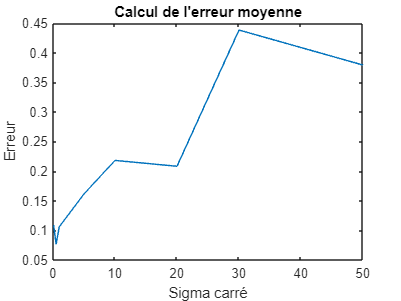


figure;
plot(sigmaBruit, error);
title("Calcul de l'erreur moyenne");
xlabel("Sigma carré"); ylabel("Erreur");

*Question 1 :** Conclure sur l'effet de sigma.*

On voit sur le graphique précédent que lorsque sigma carré (la variance) augmente, l'erreur moyenne aussi.

*Question 2 :**  Montrer l’influence de la variance sur les données obtenues avec la fonction SIM (on pourra également tracer la distribution gaussienne en fonction de la variance pour appuyer ses propos.*

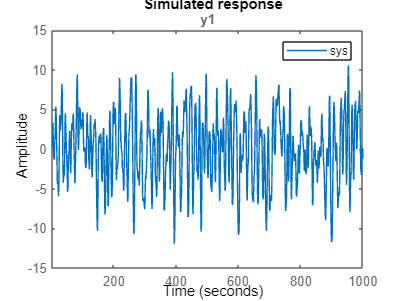

% Tracé des Gaussiennes

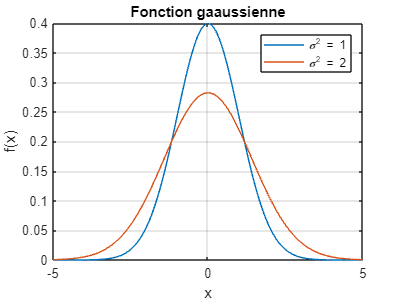

x = -5:0.01:5;
f1 = myGauss(x, 0, 1);
f2 = myGauss(x, 0, 2);

figure;
plot(x, f1, x, f2);
xlabel("x"); ylabel("f(x)");
title("Fonction gaussienne");
grid on;
legend("\sigma^2 = 1","\sigma^2 = 2");

D'après les résultats de la question 1, nous savons que lorsque la variance augmente, notre estimation s'écarte de notre modèle.

Cela s'explique par le fait que lorsque la variance augmente, le bruit est de plus en plus écarté de la valeur moyenne (moins centré autour de celle-ci), ce qui viens rajouter des erreurs lors de notre estimation.

## 2 - Méthode d'estimation paramétrique

### 2.1 - Etude de la méthode ARX

*Question 1 :** Tester l’influence du choix de la structure du modèle (degré du numérateur, degré du dénominateur, retard), et l’influence de la variance du bruit sur le résultat.*

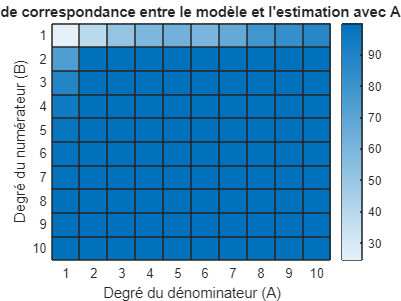

%% Définition des polynomes de notre système
A  = [1, -1.5, 0.7];
B = [0, 1, 0.5];
C = 1;
D = 1; F = 1;

%Modèle ARX sans bruit
myfit = zeros(10);
for a=1:10
    for b=1:10
        sys = idpoly(A,B,C,D,F,0,Ts);
        u = idinput(N, 'rbs');
        y = sim(sys, u);
        data = iddata(y,u,Ts);
        htest = arx(data, [a,b,1]);
        [ymod,fit,ic] = compare(data,htest);
        myfit(a,b) = fit;
    end
end
figure;
heatmap(myfit)
title("Taux de correspondance entre le modèle et l'estimation avec ARX");
xlabel("Degré du dénominateur (A)");
ylabel("Degré du numérateur (B)");

En lisant directement sur la Heatmap, on observe que la correspondance entre le modèle et l'estimation par la méthode ARX, est très élevée (100 %) pour des degrés de numérateur et de dénominateur supérieurs à 2. Ainsi pour minimiser le temps de calcul, nous pouvons prendre comme degré de numérateur et dénominateur : **(na, nb) = (2, 2)**.

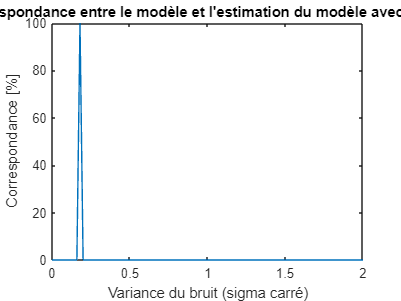

%% Modèle ARX avec bruit
varnoise=[0:0.02:2];
var_noise = zeros(1, length(varnoise));

for i=1:length(varnoise)
    sys = idpoly(A,B,C,D,F,varnoise(i),Ts);
    u = idinput(N, 'rbs');
    y = sim(sys, u);
    data = iddata(y,u,Ts);
    htest_bruit = arx(data, [2,2,1]);
    [ymod,fit,ic] = compare(data,htest_bruit);
    var_noise(a) = fit;
end
figure;
plot(varnoise,var_noise);
title("Correspondance entre le modèle et l'estimation du modèle avec le bruit");
xlabel("Variance du bruit (sigma carré)");
ylabel("Correspondance [%]")

La correspondance entre le modèle et l'estimation ARX est maximale pour une variance du bruit de 0.18.

*Question 2 :** Analyser la valeur des paramètres identifiés ainsi que leur incertitude.*

sys = idpoly(A,B,C,D,F,0.18,Ts);
u = idinput(N, 'rbs');
y = sim(sys, u);
data = iddata(y,u,Ts);
htest_opti = arx(data, [2,2,1]); % Correspondance à 100 %
htest_moins = arx(data, [1,5,1]); % Correspondance à 97.15 %

[A1,B1,C1,D1,F1,dA1,dB1,dC1,dD1,dF1]=polydata(htest_opti);
[A2,B2,C2,D2,F2,dA2,dB2,dC2,dD2,dF2]=polydata(htest_moins);
fprintf("Incertitude moyenne sur les coefficients de htest_opti %e\n",mean(abs([dA1, dB1])));

Incertitude moyenne sur les coefficients de htest_opti 1.504750e-17


fprintf("Incertitude moyenne sur les coefficients de htest_moins %e\n",mean(abs([dA2, dB2])));

Incertitude moyenne sur les coefficients de htest_moins 2.253863e-02


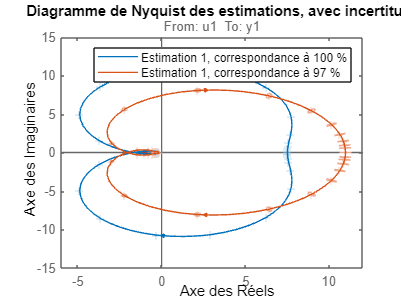



sd = 2; % Standard deviation
niq = nyquistplot(htest_opti, htest_moins);
showConfidence(niq, sd);
title("Diagramme de Nyquist des estimations, avec incertitudes");
xlabel("Axe des Réels"); ylabel("Axe des Imaginaires");
legend("Estimation 1, correspondance à 100 %", "Estimation 1, correspondance à 97 %");

On remarque que pour deux essais avec un ayant une meilleure  correspondance que l’autre, les coefficients établis sont bien meilleurs et plus précis. On observe aussi bien moins d’incertitudes sur le  diagramme de Nyquist.

### 2.2 Comparaison des méthodes ARX et ARMAX

Question 1, 2 et 3 : Analyser les résultats avec la méthodes des moindres carrés simples. Analyser aussi avec les différentes méthodes (ARX et ARMAX). Expliquez l'avantage d'une des méthodes par rapport aux autres.

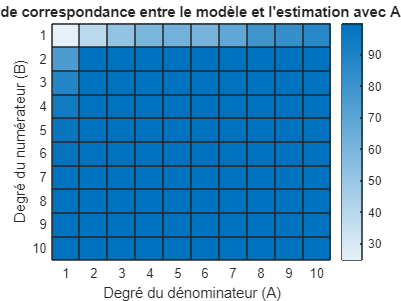

%% Définition des polynomes de notre système
A  = [1, -1.5, 0.7];
B = [0, 1, 0.5];
C = [1, -1.3, 0.9];
D = 1; F = 1;
variance = 0.1;

sys = idpoly(A,B,C,D,F,variance, Ts);
u = idinput(N, 'rbs');
y = sim(sys, u);
data = iddata(y,u,Ts);
heatmapCoeff(sys, data, 10); % Trace la heatmat de correspondace

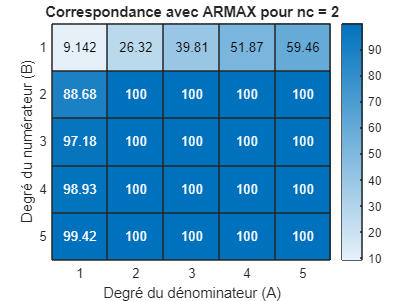

% On trouve que le jeu 2,2 est très bien (100%).
htest = arx(data, [2,2,1]);


figure;
heatmapCoeffArmax(sys, data, 5, 2)
title("Correspondance avec ARMAX pour nc = 2")

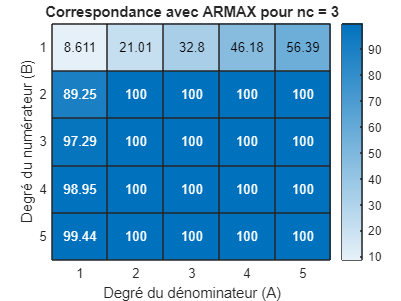

figure;
heatmapCoeffArmax(sys, data, 5, 3)
title("Correspondance avec ARMAX pour nc = 3")

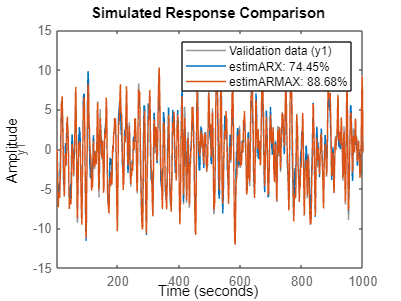


estimARMAX = armax(data, [2,1,2,1]);
estimARX=arx(data, [2,1,1]);
figure;
compare(data,estimARX,estimARMAX);

Après avoir sélectionné les  meilleurs coefficients pour les essais avec ARX et ARMAX nous avons  utilisé la fonction compare pour savoir quel modèle d’essai était le  meilleur. Nous avons pu remarquer une meilleure correspondance pour le  modèle ARMAX: cela est dû au fait que les erreurs de prédiction sont  mises à jour à chaque itération dans cette méthode. La méthode ARX est  plus utilisé s’il y a simplement un bruit blanc gaussien sans polynôme.

### Conclusion

Ce TP nous a permis d'améliorer nos connaissance sur le cours ainsi que d'avoir pu mettre en pratique les méthodes vues en cours. Nous avons aussi pu modifier les paramètres de celles-ci et voir leur effet.

function htest = estimateImpulse(N, sys, Ts)
    % Définition de nos input
    u = idinput(N, 'rbs');
    y = sim(sys, u);
    data = iddata(y,u,Ts);
    htest = cra(data, 50, 10, 0);
end

function htest = estimateImpulseNoise(N, sys, Ts)
    % Définition de nos input
    u = idinput(N, 'rbs');
    y = sim(sys, u, 'Noise');
    data = iddata(y,u,Ts);
    htest = cra(data, 50, 10, 0);
end

function f = myGauss(x, mu, sigma2)
    f = (1 / sqrt(2 * pi * sigma2)) * exp(-((x - mu).^2) / (2 * sigma2));
end


function heatmapCoeff(sys, data, n_max)
    %Modèle ARX sans bruit
    myfit = zeros(n_max);
    for a=1:n_max
        for b=1:n_max
            htest = arx(data, [a,b,1]);
            [ymod,fit,ic] = compare(data,htest);
            myfit(a,b) = fit;
        end
    end
    figure;
    heatmap(myfit)
    title("Taux de correspondance entre le modèle et l'estimation avec ARX");
    xlabel("Degré du dénominateur (A)");
    ylabel("Degré du numérateur (B)");
end

function heatmapCoeffArmax(sys, data, n_max, c)
    %Modèle ARX sans bruit
    myfit = zeros(n_max);
    for a=1:n_max
        for b=1:n_max
            htest = armax(data, [a,b,c,1]);
            [ymod,fit,ic] = compare(data,htest);
            myfit(a,b) = fit;
        end
    end
    figure;
    heatmap(myfit)
    title("Taux de correspondance entre le modèle et l'estimation avec ARX");
    xlabel("Degré du dénominateur (A)");
    ylabel("Degré du numérateur (B)");
end